B = B(:);
%CREATING THE HISTOGRAM FROM B (THE FIRST LETTERS IN EACH CODE IS THE DATA)
clf;
hold on;
LegHandles = []; LegText = {};


[CdfF,CdfX] = ecdf(B,'Function','cdf'); 
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(B,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.333333 0 0.666667],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'data';


XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XContinuous = linspace(XLim(1),XLim(2),100);
XIncr = max(1,floor((XLim(2)-XLim(1))/100));
XDiscrete = floor(XLim(1)):XIncr:ceil(XLim(2));
%CREATING ERROR BARS
elements=[3 18 26 18 18 8 6 2 0 0 1];
normalizedelements=[0.03 0.18 0.26 0.18 0.18 0.08 0.06 0.02 0 0 0.01];
bincenters= 0.5:1:10.5;
err=sqrt(elements)/100;
bar(bincenters, normalizedelements);

errorbar(bincenters,normalizedelements, err,'o');
%POISSON
pd1 = fitdist(B, 'poisson')

pd1 =   PoissonDistribution

  Poisson distribution
    lambda = 2.97   [2.63223, 3.30777]


XGrid = XDiscrete;
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','.', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'poisson';
%GAUSS

pd2 = fitdist(B, 'normal')

pd2 =   NormalDistribution

  Normal distribution
       mu =    2.97   [2.61054, 3.32946]
    sigma = 1.81161   [1.5906, 2.1045]


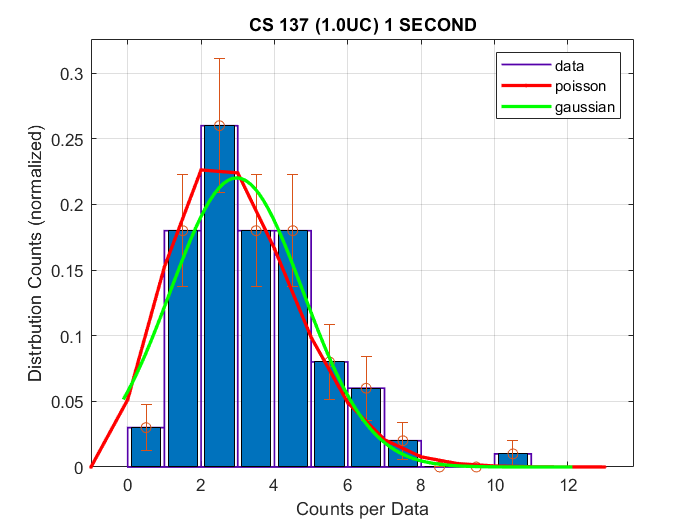

XGrid = XContinuous;
YPlot = pdf(pd2,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0 1 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'gaussian';

grid on;
box on;
hold off;


hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 9, 'Location', 'northeast');
set(hLegend,'Interpreter','none');

xlim([-1.0 13.8])
ylim([0.000 0.326])
title('CS 137 (1.0UC) 1 SECOND')
xlabel('Counts per Data')
ylabel('Distrbution Counts (normalized)')